PAY_st.name='PAY';
PAY_st.lat=46.8131; 
PAY_st.lon=6.9444;
PAY_st.alt=489;

PAY_st.env='con';
PAY_st.footp='RB';

%import xls file
PAY_rdH=table2timetable(PAYAEBabsMM10);

PAY_rd=retime(PAY_rdH,'daily',@nanmedian);

datevec(PAY_rd.Time(1))

ans =         2008           1           1           0           0           0


datevec(PAY_rd.Time(end))

ans =         2019           1           1           0           0           0


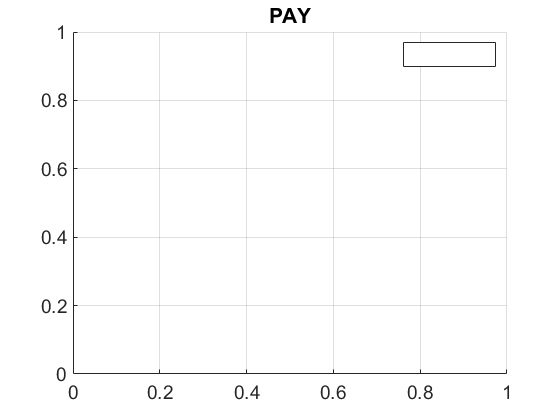

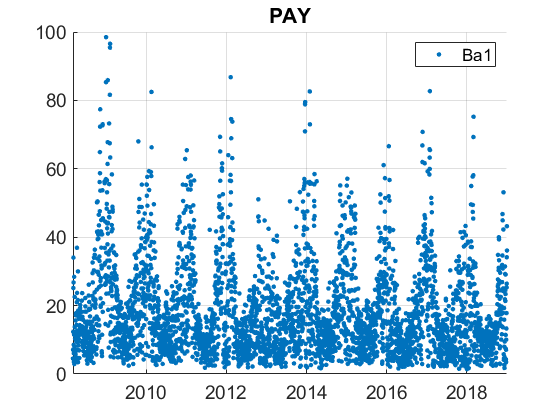

%prctile(PAY_rd.U_S11,[5 50 95])

plotFigControl(PAY_rd,PAY_st.name);

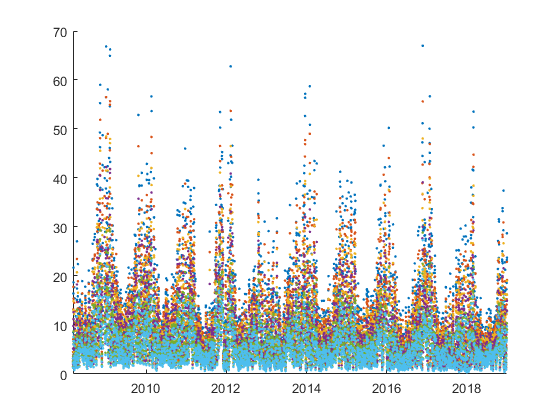

hold on;
plot(PAY_rd.Time,PAY_rd.Ba2,'.');
plot(PAY_rd.Time,PAY_rd.Ba3,'.');
plot(PAY_rd.Time,PAY_rd.Ba4,'.');
plot(PAY_rd.Time,PAY_rd.Ba5,'.');
plot(PAY_rd.Time,PAY_rd.Ba6,'.');
plot(PAY_rd.Time,PAY_rd.Ba7,'.');

% 1 size cut, 
% sc: ok, no clear seasonal cycle, no negatives
%abs: max in winter
%abs: change 1w to 3w end of 2005,change to CLAP in 2013 some negatives, abs maxima in winter
%abs: ratio between w: clear seasonal cycle, max in winter

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
%PAY_rd=compute_exp_SSA(PAY_rd,lambdaSC, lambdaAE);plotFigControl_cal(PAY_rd, PAY_st.name);

        PAY_rd.expA_bg=real(-log(PAY_rd.Ba2./PAY_rd.Ba3)/log(470/520));
        PAY_rd.expA_br=real(-log(PAY_rd.Ba2./PAY_rd.Ba5)/log(470/660));
        PAY_rd.expA_gr=real(-log(PAY_rd.Ba3./PAY_rd.Ba5)/log(520/660));
     
        PAY_rd.expA_12=real(-log(PAY_rd.Ba1./PAY_rd.Ba2)/log(370/470));
        PAY_rd.expA_45=real(-log(PAY_rd.Ba4./PAY_rd.Ba5)/log(590/660));
        PAY_rd.expA_56=real(-log(PAY_rd.Ba5./PAY_rd.Ba6)/log(660/880));
        PAY_rd.expA_67=real(-log(PAY_rd.Ba6./PAY_rd.Ba7)/log(880/920));
        
        all_Abs=[PAY_rd.Ba1 PAY_rd.Ba2 PAY_rd.Ba3 PAY_rd.Ba4 PAY_rd.Ba5 PAY_rd.Ba6 PAY_rd.Ba7];
        PAY_rd.expA_fit=Exp_AE_nan_regr(all_Abs);

SCexclus = 0

ans = 5

ans = 95

ans = 0

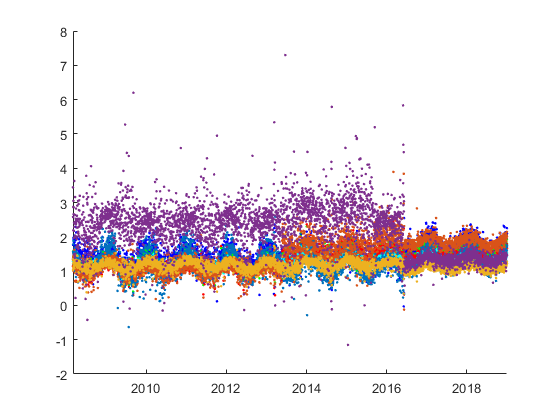

%     end
figure;
hold on;
 plot(PAY_rd.Time, PAY_rd.expA_bg,'.b');
 plot(PAY_rd.Time, PAY_rd.expA_br,'.g');
  plot(PAY_rd.Time, PAY_rd.expA_gr,'.r');
 plot(PAY_rd.Time, PAY_rd.expA_fit,'.c');
 
  plot(PAY_rd.Time, PAY_rd.expA_12,'.');
 plot(PAY_rd.Time, PAY_rd.expA_45,'.');
  plot(PAY_rd.Time, PAY_rd.expA_56,'.');
  plot(PAY_rd.Time, PAY_rd.expA_67,'.');

%Questions:
%problems:none

%abs: seems ok

PAY_tr=PAY_rd;

PAY_tr.y=year(PAY_tr.Time);
% begin at the beginning of a year: 2001 (2000??: ok it will not change the 10-15y,20y not possible anyhow since begin february)
%end: 2017
P=timerange('2009-01-01','2019-01-01');
PAY_tr=PAY_tr(P,:);

%compute trend on B, G and R
PAY_tr.Ba1=[];
PAY_tr.Ba4=[];
PAY_tr.Ba6=[];
PAY_tr.Ba7=[];
%only expA 12 and 56
PAY_tr.expA_br=[];
PAY_tr.expA_gr=[];
PAY_tr.expA_bg=[];
PAY_tr.expA_fit=[];
PAY_tr.expA_67=[];
PAY_tr.expA_45=[];

PAY_result= all_trend_STN(PAY_tr,PAY_st); 


PAY_result_D=PAY_result;
%result on 520 nm only
% no expA without Christoph feedback
PAY_result_D=Pay_result_D(strcmp(Pay_result_D.parameter,'Ba3')==1,:);
